# This in the code to reproduce the results of Section III.C of the paper  "PanSuite: A Free Simulation Environment for the Analysis of Hybrid Electrical Power Systems"

## 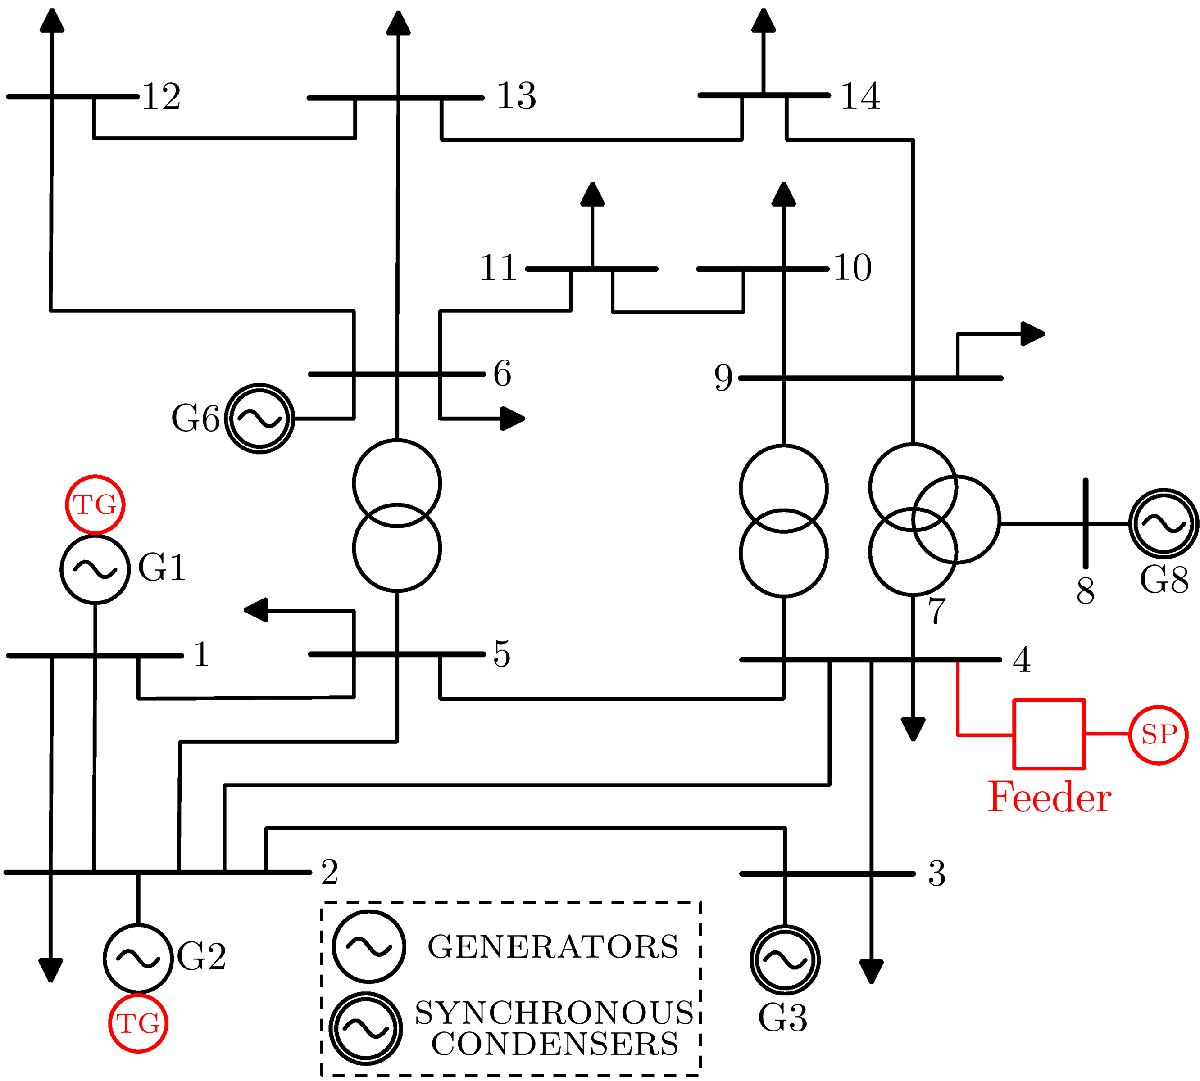

## Hybrid power system parameters value

F0 = 50;
VBASE = 230E3;
PBASE = 100E6;
TSTOP = 20*50E-3;
CLK_PERIOD = (1/4)/F0;
OMEGA = 2*pi*F0;
VDC_REF = 660;
RD = 1001E6;
D = 2;
VDIG = 1;
OMEGA = 2*pi*F0;
VDC_REF = 660;
RD = 100E6;
MULT_DIS = 800;
MULT_PV = 4*2;
N_SERIES_PV = 8;
LOW_IRR = 200;
HIGH_IRR = 1E3;
ENV_START = TSTOP+16*CLK_PERIOD;
ENV_STOP  = ENV_START+29E3*CLK_PERIOD;
T_IRR_STOP_SWEEP = ENV_START+10E3*CLK_PERIOD;

## Load the PAN netlist


MPanLoadNet('ieee14Feeder.pan')

Unrecognized function or variable 'MPanLoadNet'.

global MPanerror
MPanerror = 0;
% Turn off displaying of single character or string. Output is in chunks.
% To augment display granularity comment the following line.
panredraw('off');

## Perform a time domain analysis to initialise the three-phase part of the circuit model. The single-phase model of the hybrid power system is ignored.


MPanTran('Tr1', TSTOP+0.2*CLK_PERIOD, [], 'uic', 2, 'restart', true, ...
    'ireltol', 1E-3, 'iabstol', 1E-6, 'nettype', 'no', 'annotate', 5, ...
    'acntrl', 3);
if MPanerror>0
  error('Something went wrong with the PAN analysis!')
end

## Compute the steady state solution of the three-phase part of the circuit model. The last time point by the previous transient analysis is used as initial guess. The single-phase model of the hybrid power system is still ignored.

MPanShooting('ShI', [], 'fund', 'F0',  'restart', false,  'solver', '0', ...
    'floquet', true, 'method', 2,  'maxord', 2, 'damping', 0.4, ...
    'tmax', '1m/F0', 'iabstol', 1E-9, 'nettype', 'no', ...
    'ereltol', 5E-3);
if MPanerror>0
    error('Something went wrong with the PAN analysis!')
end

## Compute the power flow solution of the single-phase model of the hybrid power systems. The three-phase model is ignored.

MPanDc('Dc', [], 'nettype', 2, 'print', true, 'sparse', 2, ...
    'gminstepping', false, 'ggroundstepping', false)
if MPanerror>0
    error('Something went wrong with the PAN analysis!')
end

## Compute the shooting-power flow solution, i.e. the steady state solution of the full hybrid power system described in the 'dq'-frame and in the 'abc'-frame.

MPanShooting('ShPf', [], 'fund', 'F0',  'solver', 0,  'floquet', true, ...
    'method', 2, 'maxord', 2, ...
    'nettype', 3, 'restart', false, ...
    'tmax', '1m/F0', 'ereltol', 1E-3, 'eabstol', 1E-3, ....
    'devvars', true, 'printmo', 0, 'trabstol', 10E-9, 'iabstol', 1E-9)
if MPanerror>0
    error('Something went wrong with the PAN analysis!')
end

## Perform a short time domain analysis of the entire hybrid power system to cancell out possibly very small perturbations by the previous shooting-power flow analysis.

MPanTran('TrZ', ENV_START, [], 'savetime', TSTOP+4*CLK_PERIOD, ...
    'restart', false, 'ireltol', 1E-3, 'iabstol', 1E-6, 'nettype', 1, ...
    'method', 2, 'maxord', 2);
if MPanerror>0
    error('Something went wrong with the PAN analysis!')
end

## Perform the envelope analysis by starting from the last time point computed by the previous time domain analysis.

MEM_VARS = ["time","omega01","omega02","pm01","pm02","Solar.pos","Solar.S"];
Env_output = MPanEnvelope('Env', ENV_STOP, MEM_VARS, 'fund', 'F0', ...
    'method', 2, 'maxord', 2, 'nettype', 1, 'restart', false, ...
    'ireltol', 1E-3, 'iabstol', 1E-6, 'mktpu', true, 'acntrl', 3, ...
    'devvars', 1, 'ltefactor', 1);
if MPanerror>0
    error('Something went wrong with the PAN analysis!')
end

## Produce the figures reported in the paper

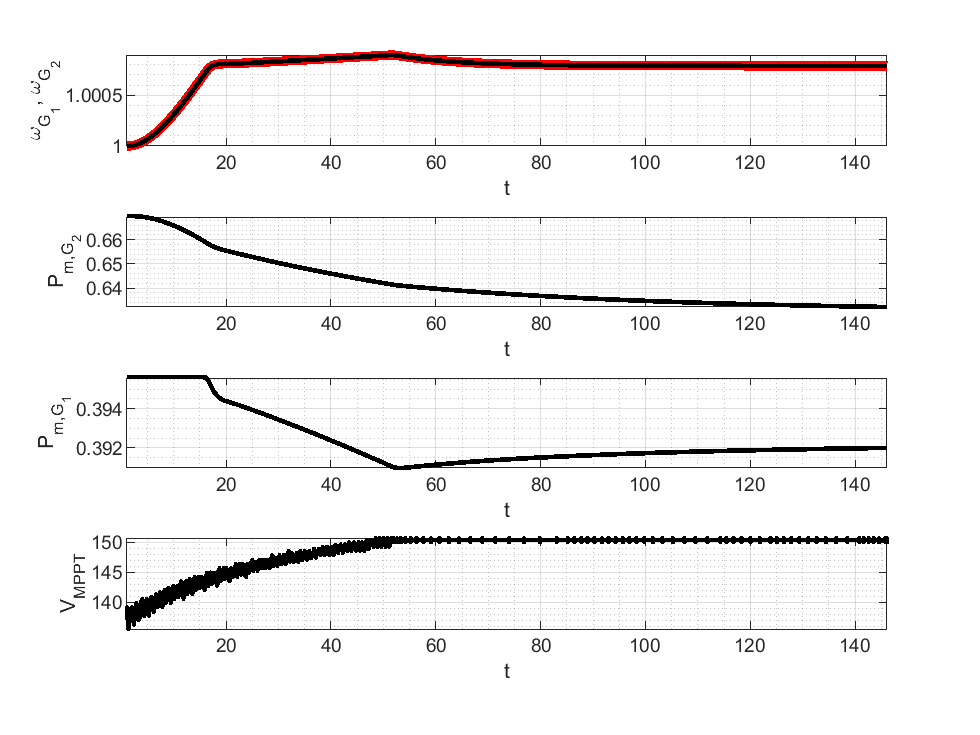

time = Env_output{1}.signal;
omega_G1 = Env_output{2}.signal;
omega_G2 = Env_output{3}.signal;
PmG1 = Env_output{4}.signal;
PmG2 = Env_output{5}.signal;
Vmppt = Env_output{6}.signal;
figure
subplot(4,1,1)
plot(time, omega_G1,'Color','r','LineWidth',4);
hold on
plot(time, omega_G2,'Color','k','LineWidth',2);
axis tight
grid on
grid minor
xlabel('t')
ylabel('\omega_{G_1}, \omega_{G_2}')

subplot(4,1,2)
plot(time, PmG2,'Color','k','LineWidth',2);
axis tight
grid on
grid minor
xlabel('t')
ylabel('P_{m,{G_2}}')

subplot(4,1,3)
plot(time, PmG1,'Color','k','LineWidth',2);
axis tight
grid on
grid minor
xlabel('t')
ylabel('P_{m,{G_1}}')

subplot(4,1,4)
plot(time, Vmppt,'Color','k','LineWidth',2);
axis tight
grid on
grid minor
xlabel('t')
ylabel('V_{MPPT}')